load("PointFangXing.mat")
% 随机生成一组（x,y,z),这些点的坐标离一个空间平面比较近
x0=1,L1=2;

x0 = 1

y0=1,L2=2;

y0 = 1

x=x0+rand(20,1)*L1;
y=y0+rand(20,1)*L2;
z=1+2*x+3*y+rand(20,1)*3;% 随机生成一组（x,y,z),这些点的坐标离一个空间平面比较近

Points = [x';y';z'];

PlaneParaIn = [];

[PlaneParaOut,TrianglePoints] = planefit(Points,PlaneParaIn)

c = -1

PlaneParaOut =     2.1472
    3.3390
   -1.0000
    1.4467


TrianglePoints =     1.0999    1.0999    2.9842    1.0999    2.9842    2.9842
    2.9790    1.0628    1.0628    2.9790    1.0628    2.9790
   13.7551    7.3571   11.4031   13.7551   11.4031   17.8011


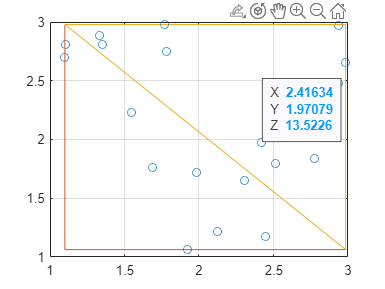



figure;hold on;
scatter3(x,y,z)
plot3(TrianglePoints(1,[1:3,1]),TrianglePoints(2,[1:3,1]),TrianglePoints(3,[1:3,1]))
plot3(TrianglePoints(1,[4:6,4]),TrianglePoints(2,[4:6,4]),TrianglePoints(3,[4:6,4]))
box on
grid on